# Newton Method

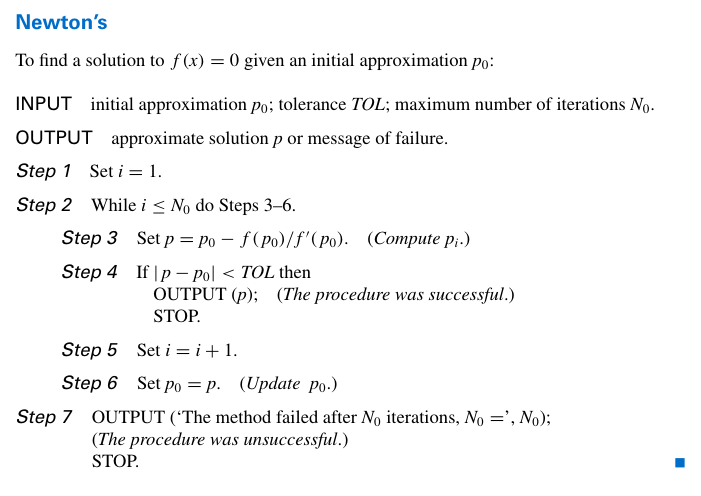

## Initialization

clc;
clear;
close all; % Clear before

## Add initial condition

tol = 1.e-10;           % Tolorence of result
nmax = 100;             % Maximum number of iterations
p_1 = -1;                % Initial Prediction value
xmin = -1;               % Min x of plot interval
xmax = 2;            % Max x of plot interval
itcount = 0;            % Number of initialization iterations
error = 10000;          % Error initialization

## Plot the graph

About the drawing related parameters, and start the graphic diagram to draw simple pictures


xval = linspace(xmin,10,100); 
for i=1:100
    fval(i) = func(xval(i));        % Calculate function image points
end
plot(xval,fval,"Color","k","LineWidth",1);                    % Plot the function

Start point calculation:

grid on;
hold on;
while (itcount <= 4)  % When the number of iterations does not overflow, the error is still too large
    itcount =itcount+1;
    p = p_1-func(p_1)/funcdiff(p_1);    % Iteration function of the Newton's Method
    z(itcount) = p;                     % Record the result into the dataset
    p_1=p;
    if itcount == 5
    p_final=p
    end

end

p_final =    9.402151960310778


Plot the Graph

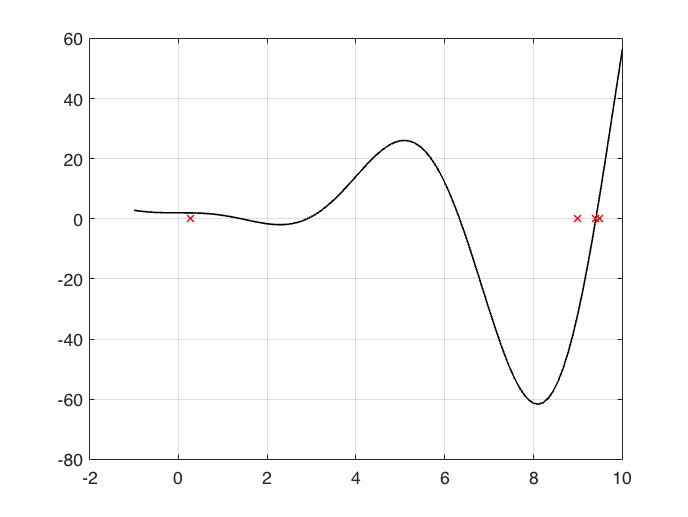

plot(z(1:itcount),zeros(itcount,1),'rx',LineWidth=1); % Plot the point with the dataset

if (itcount <nmax)
    val = func(p);
    fprintf('Converged solution after %d iterations',itcount);
    fprintf(' is %.7e\n',p_final);
else
    fprinf('Not converged after %5d iterations',namx);
end

Converged solution after 5 iterations

 is 9.4021520e+00


Here plot the tangent line on initial point

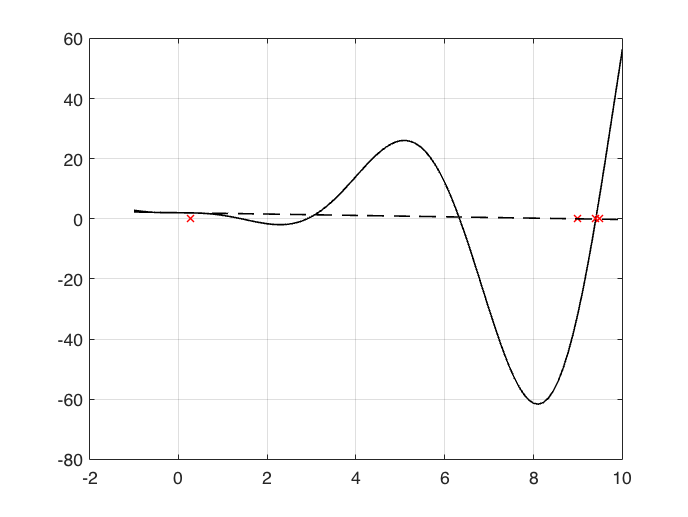

xt=linspace(xmin,10,100);
yt=funcdiff(z(1))*(xt-z(1))+func(z(1));
plot(xt,yt,"LineStyle","--","LineWidth",1,"Color",'k')

hold off

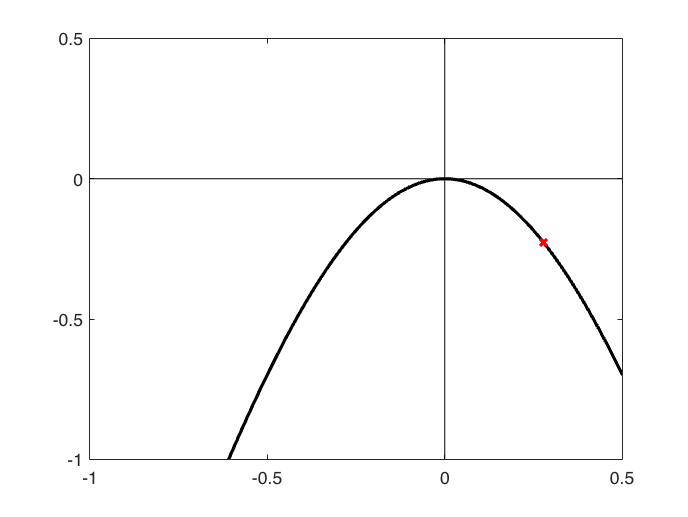

xval = linspace(xmin,0.5,100); 
for i=1:100
    fval(i) = funcdiff(xval(i));        % Calculate function image points
end
plot(xval,fval,"Color","k","LineWidth",2);   
hold on
plot(z(1),funcdiff(z(1)),'rx',"LineWidth",2);
ylim ([-3 1]);
ylim ([xmin 0.5]);
line([0 0],[xmin 0.5],'color','k');
line([xmin 0.5],[0 0],'color','k');

## Appendix: Function

Here is an Example of the function

function val = func(x)
    val = 2-x^2*sin(x);
end

Here is the derivative of the above function

function val = funcdiff(x)
    val = -2*x*sin(x)-x^2*cos(x);
end